# Graficos Estadisticos

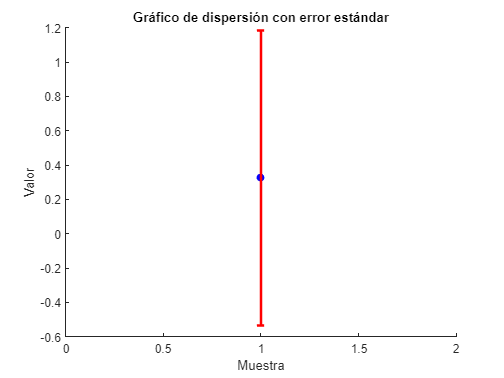

% Datos de ejemplo
data = randn(1, 10);  % Datos aleatorios para ilustrar el ejemplo
media = mean(data);
desvio_estandar = std(data);

% Crear el gráfico de dispersión
scatter(1, mean(data), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');

hold on;  % Mantener el gráfico actual para agregar el punto y la línea de error

% Agregar línea de error
errorbar(1, mean(data), desvio_estandar, 'r', 'LineStyle', 'none', 'LineWidth', 2);  % 'r' para color rojo

hold off;  % Liberar el gráfico

% Etiquetas y título
xlabel('Muestra');
ylabel('Valor');
title('Gráfico de dispersión con error estándar');

Otro grafico:

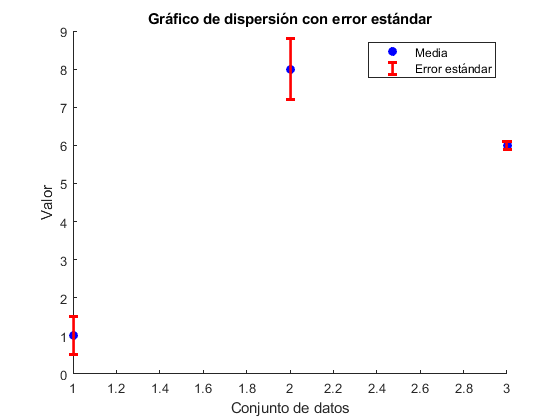

% Vectores de promedios y desvíos estándar
promedios = [1, 8, 6];
desvios_estandar = [0.5, 0.8, 0.1];

% Número de conjuntos de datos
num_datasets = length(promedios);

% Crear un gráfico de dispersión con barras de error
figure;

for i = 1:num_datasets
    % Coordenada x para cada conjunto de datos
    x_coordinate = i * ones(size(promedios(i)));

    % Crear el gráfico de dispersión con errorbar
    scatter(x_coordinate, promedios(i), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');
    hold on;
    errorbar(x_coordinate, promedios(i), desvios_estandar(i), 'r', 'LineStyle', 'none', 'LineWidth', 2);
end

hold off;

% Etiquetas y título
xlabel('Conjunto de datos');
ylabel('Valor');
title('Gráfico de dispersión con error estándar');

% Leyenda
legend('Media', 'Error estándar');

Otro ejemplo:

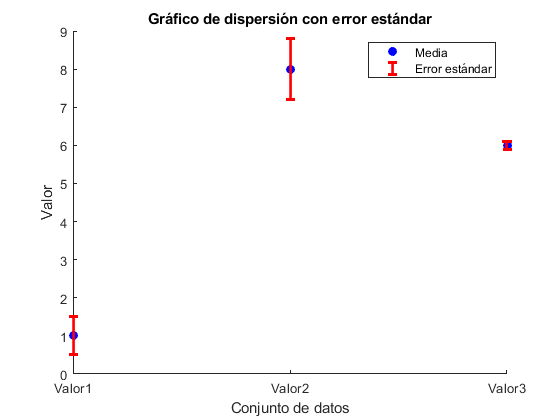

% Vectores de promedios y desvíos estándar
promedios = [1, 8, 6];
desvios_estandar = [0.5, 0.8, 0.1];

% Número de conjuntos de datos
num_datasets = length(promedios);

% Etiquetas para el eje x
etiquetas = {'Valor1', 'Valor2', 'Valor3'};

% Crear un gráfico de dispersión con barras de error
figure;

for i = 1:num_datasets
    % Crear el gráfico de dispersión con errorbar
    scatter(i, promedios(i), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');
    hold on;
    errorbar(i, promedios(i), desvios_estandar(i), 'r', 'LineStyle', 'none', 'LineWidth', 2);
end

hold off;

% Etiquetas y título
set(gca, 'XTick', 1:num_datasets, 'XTickLabel', etiquetas);
xlabel('Conjunto de datos');
ylabel('Valor');
title('Gráfico de dispersión con error estándar');

% Leyenda
legend('Media', 'Error estándar');

## Graficos más reales:

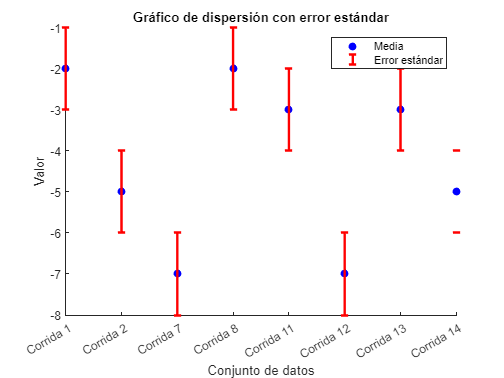

% Vectores de promedios y desvíos estándar
deformacion_residual_experimento = [
-2,97E-04
-5,03E-04
-7,28E-05
-2,20E-05
-3,47E-04
-7,81E-04
-3,62E-04
-5,38E-04

];
desvios_estandar = [
1,95E-05
1,95E-05
1,95E-05
1,95E-05
1,95E-05
1,95E-05
1,95E-05
1,95E-05
];

% Etiquetas para el eje x
etiquetas = {'Corrida 1', 'Corrida 2', 'Corrida 7','Corrida 8', 'Corrida 11', 'Corrida 12','Corrida 13', 'Corrida 14'};

% Crear un gráfico de dispersión con barras de error
figure;

for i = 1:8
    % Crear el gráfico de dispersión con errorbar
    scatter(i, deformacion_residual_experimento(i), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');
    hold on;
    errorbar(i, deformacion_residual_experimento(i), desvios_estandar(i), 'r', 'LineStyle', 'none', 'LineWidth', 2);
end

hold off;

% Etiquetas y título
set(gca, 'XTick', 1:8, 'XTickLabel', etiquetas);
xlabel('Conjunto de datos');
ylabel('Valor');
title('Gráfico de dispersión con error estándar');

% Leyenda
legend('Media', 'Error estándar');

Otros graficos mas reales:

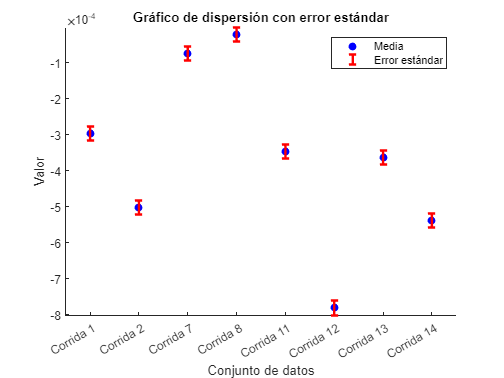

% Vectores de promedios y desvíos estándar
deformacion_residual_experimento = [
    -2.97E-04
    -5.03E-04
    -7.28E-05
    -2.20E-05
    -3.47E-04
    -7.81E-04
    -3.62E-04
    -5.38E-04
];
desvios_estandar = [
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
];

% Etiquetas para el eje x
etiquetas = {'Corrida 1', 'Corrida 2', 'Corrida 7', 'Corrida 8', 'Corrida 11', 'Corrida 12', 'Corrida 13', 'Corrida 14'};

% Crear un gráfico de dispersión con barras de error
figure;

for i = 1:8
    % Crear el gráfico de dispersión con errorbar
    scatter(i, deformacion_residual_experimento(i), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');
    hold on;
    errorbar(i, deformacion_residual_experimento(i), desvios_estandar(i), 'r', 'LineStyle', 'none', 'LineWidth', 2);
end

hold off;

% Ajustar los límites de los ejes x e y
xlim([0.5, 8.5]);  % Ajustar los límites del eje x
ylim([min(deformacion_residual_experimento - desvios_estandar), max(deformacion_residual_experimento + desvios_estandar)]);  % Ajustar los límites del eje y

% Etiquetas y título
set(gca, 'XTick', 1:8, 'XTickLabel', etiquetas);
xlabel('Conjunto de datos');
ylabel('Valor');
title('Gráfico de dispersión con error estándar');

% Leyenda
legend('Media', 'Error estándar');

otra prueba:

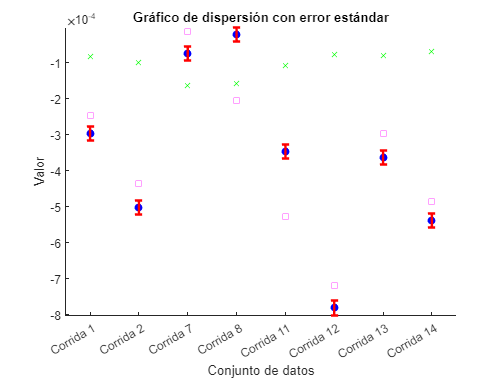

% Vectores de promedios y desvíos estándar
deformacion_residual_experimento = [
    -2.97E-04
    -5.03E-04
    -7.28E-05
    -2.20E-05
    -3.47E-04
    -7.81E-04
    -3.62E-04
    -5.38E-04];

desvios_estandar = [
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05];

deformacion_residual_predicha = [
-8.11E-05
-9.83E-05
-1.63E-04
-1.58E-04
-1.07E-04
-7.72E-05
-7.90E-05
-6.78E-05];

deformacion_residual_correlacion = [
-2.45E-04
-4.36E-04
-1.15E-05
-2.03E-04
-5.28E-04
-7.19E-04
-2.95E-04
-4.86E-04];


% Etiquetas para el eje x
etiquetas = {'Corrida 1', 'Corrida 2', 'Corrida 7', 'Corrida 8', 'Corrida 11', 'Corrida 12', 'Corrida 13', 'Corrida 14'};

% Crear un gráfico de dispersión con barras de error
figure;

for i = 1:8
    % Crear el gráfico de dispersión con errorbar
    scatter(i, deformacion_residual_experimento(i), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');
    hold on;
    errorbar(i, deformacion_residual_experimento(i), desvios_estandar(i), 'r', 'LineStyle', 'none', 'LineWidth', 2);
end

% Agregar gráfico de dispersión para deformacion_residual_predicha
scatter(1:8, deformacion_residual_predicha, 'Marker', 'x', 'MarkerEdgeColor', 'g');

% Agregar gráfico de dispersión para deformacion_residual_correlacion
scatter(1:8, deformacion_residual_correlacion, 'Marker', 's', 'MarkerEdgeColor', 'm');

hold off;

% Ajustar los límites de los ejes x e y
xlim([0.5, 8.5]);  % Ajustar los límites del eje x
ylim([min(deformacion_residual_experimento - desvios_estandar), max(deformacion_residual_experimento + desvios_estandar)]);  % Ajustar los límites del eje y

% Etiquetas y título
set(gca, 'XTick', 1:8, 'XTickLabel', etiquetas);
xlabel('Conjunto de datos');
ylabel('Valor');
title('Gráfico de dispersión con error estándar');

Grafico mejorado:

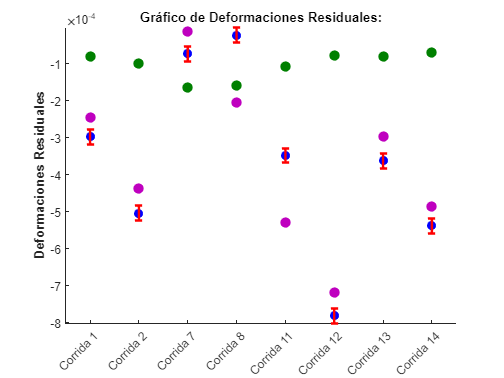

% Vectores de promedios y desvíos estándar
deformacion_residual_experimento = [
    -2.97E-04
    -5.03E-04
    -7.28E-05
    -2.20E-05
    -3.47E-04
    -7.81E-04
    -3.62E-04
    -5.38E-04
];
desvios_estandar = [
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
];

deformacion_residual_predicha = [
    -8.11E-05
    -9.83E-05
    -1.63E-04
    -1.58E-04
    -1.07E-04
    -7.72E-05
    -7.90E-05
    -6.78E-05
];

deformacion_residual_correlacion = [
    -2.45E-04
    -4.36E-04
    -1.15E-05
    -2.03E-04
    -5.28E-04
    -7.19E-04
    -2.95E-04
    -4.86E-04
];

% Etiquetas para el eje x
etiquetas = {'Corrida 1', 'Corrida 2', 'Corrida 7', 'Corrida 8', 'Corrida 11', 'Corrida 12', 'Corrida 13', 'Corrida 14'};

% Crear un gráfico de dispersión con barras de error
figure;

for i = 1:8
    % Crear el gráfico de dispersión con errorbar
    scatter(i, deformacion_residual_experimento(i), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b', 'LineWidth', 1.5);
    hold on;
    errorbar(i, deformacion_residual_experimento(i), desvios_estandar(i), 'r', 'LineStyle', 'none', 'LineWidth', 2);
end

% Agregar gráfico de dispersión para deformacion_residual_predicha
scatter(1:8, deformacion_residual_predicha, 50, 'o','MarkerFaceColor', [0, 0.5, 0], 'MarkerEdgeColor', [0, 0.5, 0], 'LineWidth', 1.5);

% Agregar gráfico de dispersión para deformacion_residual_correlacion
scatter(1:8, deformacion_residual_correlacion, 50, 'o','MarkerFaceColor', [0.75, 0, 0.75], 'MarkerEdgeColor', [0.75, 0, 0.75], 'LineWidth', 1.5);

hold off;

% Ajustar los límites de los ejes x e y
xlim([0.5, 8.5]);  % Ajustar los límites del eje x
ylim([min([deformacion_residual_experimento - desvios_estandar; deformacion_residual_predicha; deformacion_residual_correlacion]), max([deformacion_residual_experimento + desvios_estandar; deformacion_residual_predicha; deformacion_residual_correlacion])]);  % Ajustar los límites del eje y

% Etiquetas y título
set(gca, 'XTick', 1:8, 'XTickLabel', etiquetas);
ylabel('Deformaciones Residuales', 'FontWeight', 'bold');  % Ajustar el texto del eje y en negrita
title(['Gráfico de Deformaciones Residuales:']);

% Ajustar las etiquetas del eje x a 45º
xtickangle(45);

% Leyenda
legend('Def. Res. Experimental', 'Def. Res. Predicha', 'Def. Res. de Correlación');

% Ajustar las etiquetas del eje x en negrita
for i = 1:numel(etiquetas)
    text(i, min(get(gca, 'YLim')) - 0.02, etiquetas{i}, 'HorizontalAlignment', 'right', 'Rotation', 45, 'FontWeight', 'bold');
end

# Comparacion ANSYS vs. Experimentos

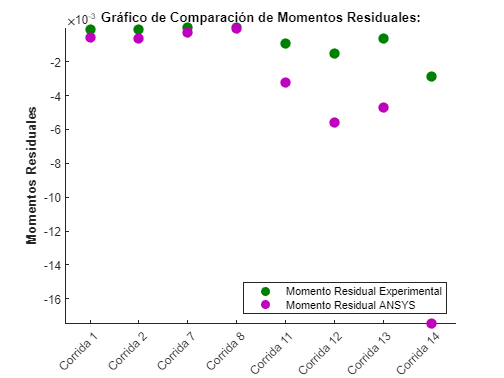

% Vectores de promedios y desvíos estándar
deformacion_residual_experimento = [
    -2.97E-04
    -5.03E-04
    -7.28E-05
    -2.20E-05
    -3.47E-04
    -7.81E-04
    -3.62E-04
    -5.38E-04
];
desvios_estandar = [
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
    1.95E-05
];

deformacion_residual_ANSYS = [
-0,516941228
-0,840940174
-0,25568566
-0,221686073
-0,278924589
-0,420501508
-0,106904031
-0,139049863
-7,68E-02
-3,08E-02
];%para momento unitario

momento_residual_experimental = [
-0.00010755
-0.00009382
-0.000002055
-0.00000033
-0.00093068
-0.00153221
-0.00063342
-0.00286919
];

momento_residual_ANSYS = [
-0.000574533
-0.00059814
-0.000272473
-5.23185E-05
-0.003245902
-0.00561669
-0.004710872
-0.017439566
];

% Etiquetas para el eje x
etiquetas = {'Corrida 1', 'Corrida 2', 'Corrida 7','Corrida 8', 'Corrida 11', 'Corrida 12', 'Corrida 13', 'Corrida 14'};


figure;
hold on;


% Agregar gráfico de dispersión para momento_residual_experimental
scatter(1:8, momento_residual_experimental, 50, 'o','MarkerFaceColor', [0, 0.5, 0], 'MarkerEdgeColor', [0, 0.5, 0], 'LineWidth', 1.5);

% Agregar gráfico de dispersión para momento_residual_ANSYS
scatter(1:8, momento_residual_ANSYS, 50, 'o','MarkerFaceColor', [0.75, 0, 0.75], 'MarkerEdgeColor', [0.75, 0, 0.75], 'LineWidth', 1.5);

hold off;

% Ajustar los límites de los ejes x e y
xlim([0.5, 8.5]);  % Ajustar los límites del eje x
ylim([min([momento_residual_experimental; momento_residual_ANSYS]), max([momento_residual_experimental; momento_residual_ANSYS])]);  
% Ajustar los límites del eje y

% Etiquetas y título
set(gca, 'XTick', 1:8, 'XTickLabel', etiquetas);
ylabel('Momentos Residuales', 'FontWeight', 'bold');  % Ajustar el texto del eje y en negrita
title(['Gráfico de Comparación de Momentos Residuales:']);

% Ajustar las etiquetas del eje x a 45º
xtickangle(45);

% Leyenda
legend('Momento Residual Experimental', 'Momento Residual ANSYS');
% Agregar la leyenda abajo a la derecha
legend('Location', 'southeast');

% Ajustar las etiquetas del eje x en negrita
for i = 1:numel(etiquetas)
    text(i, min(get(gca, 'YLim')) - 0.02, etiquetas{i}, 'HorizontalAlignment', 'right', 'Rotation', 45, 'FontWeight', 'bold');
end